# Building of context-specific models using rFASTCORMICS (Pacheco et al, 2019)

%add path the cobra 
path='C:\Users\maria.pacheco\OneDrive - University of Luxembourg\Desktop';
%optional
set(0,'defaultTextInterpreter','none');
set(groot,'defaulttextinterpreter','none');
set(groot, 'DefaultAxesTickLabelInterpreter', 'none');
set(groot, 'defaultLegendInterpreter','none');
%Uncomment if an error related to eval occurs
%feature astheightlimit 2000
% color code used for the heat maps
altcolor= [255 255 255;255 204 204; 255 153 153; 255 102 102; 255 51 51;...
    255 0 0; 204 0 0; 152 0 0; 102 0 0;  51 0 0]/255; %shorter 10% = 1 bar

delete clone*.log %delete some files generated by cplex

## 3.1 Expression data input

Import the gene expression data into Matlab. 

data_cancer = readtable('fpkm_BRCA_cancer.txt', "ReadRowNames",true);
data_control = readtable('fpkm_BRCA_control.txt', "ReadRowNames",true);
data = [data_cancer, data_control];
fpkm = table2array(data);
rownames = data.Properties.RowNames;
colnames = data.Properties.VariableNames;

## 3.2. Context-specific model reconstruction

human reconstruction Recon 3

load('Recon3Model.mat')

## load medium - dictionnaries -

load mediumExample.mat
load dicorFASTCORMICS.mat

epsilon = 1e-4;
consensusProportion = 0.9;
%unnest the model.subSystems
if ischar(model.subSystems{1})
else
    model.subSystems=vertcat(model.subSystems{:});
end

unpenalizedSystems = {'Transport, endoplasmic reticular';
    'Transport, extracellular';
    'Transport, golgi apparatus';
    'Transport, mitochondrial';
    'Transport, peroxisomal';
    'Transport, lysosomal';
    'Transport, nuclear'};
unpenalized = model.rxns(ismember(model.subSystems,unpenalizedSystems));
optionalSettings.unpenalized = unpenalized;
optionalSettings.func = {'DM_atp_c_'}; % forced reactions
notMediumConstrained = 'EX_tag_hs(e)';% if no constrain is used please remove the field.
optionalSsettings.notMediumConstrained = notMediumConstrained;
optionalSettings.medium = medium_example;% if no medium is used please remove the field.

biomassReactionName = {'biomass_reaction'};
printFigures=1;
changeCobraSolver('ibm_cplex');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2022b.


## Reconstruct the context-specific models

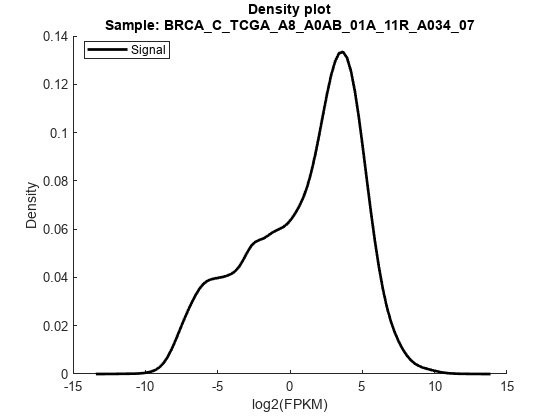

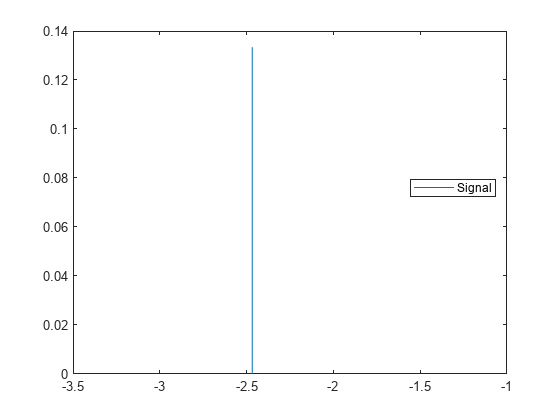

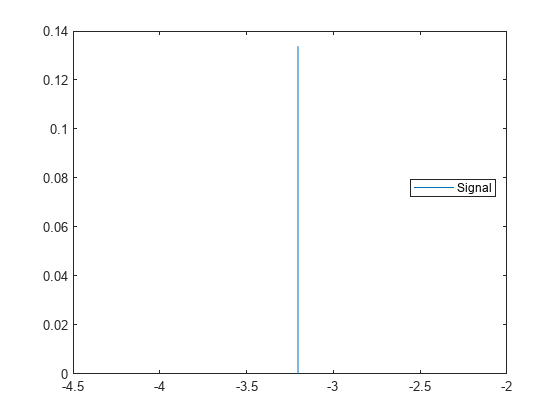

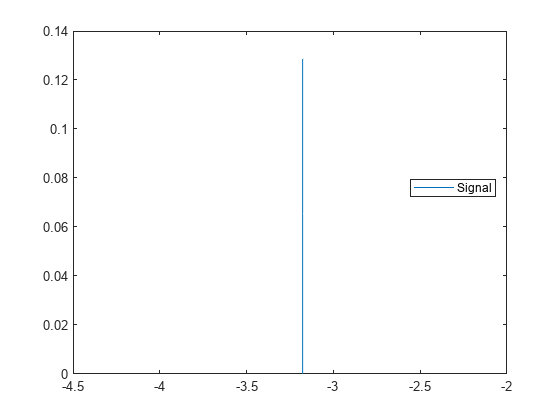

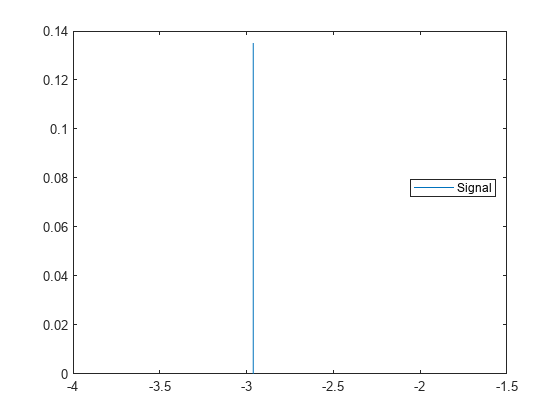

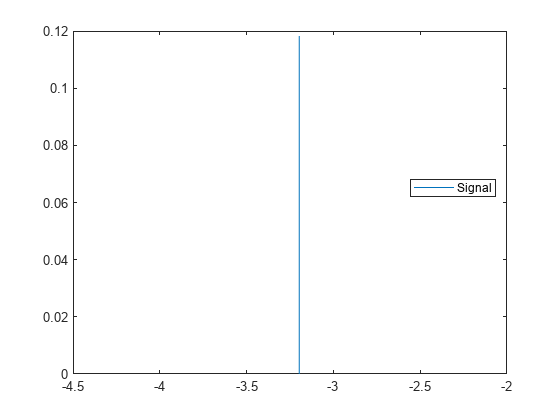

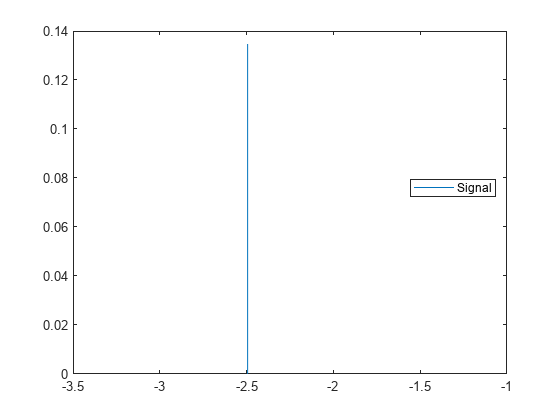

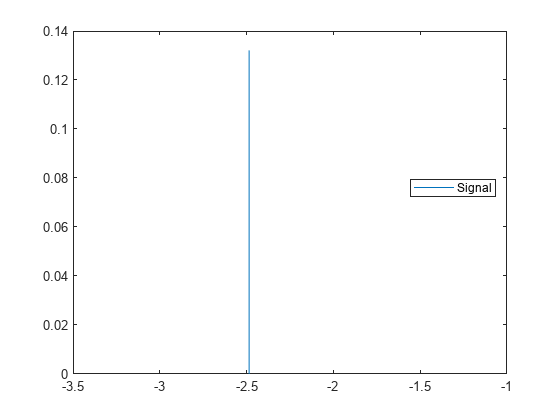

2119 of 2248 genes matched


[indexCancerConsensus]=rFastcormics4cobra(model, fpkm(:,1:10), rownames, colnames(1:10),dico, consensusProportion, epsilon, optionalSettings, biomassReactionName, printFigures, path);

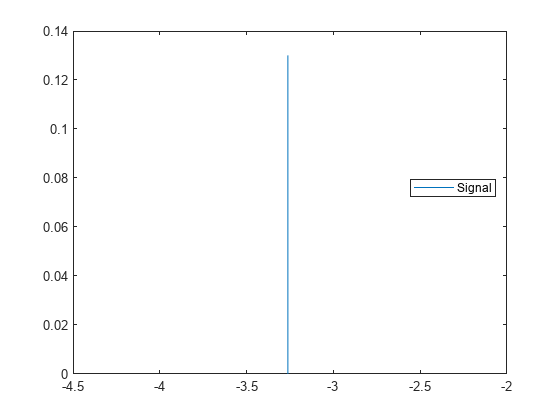

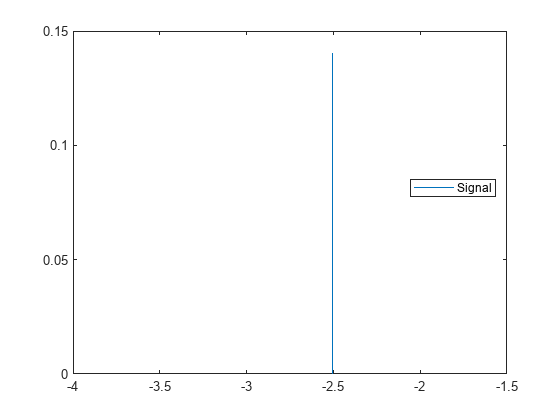

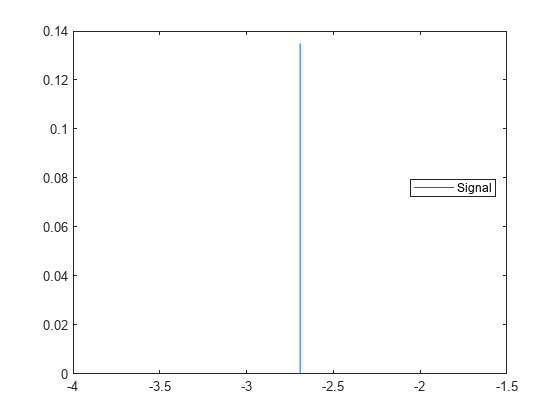

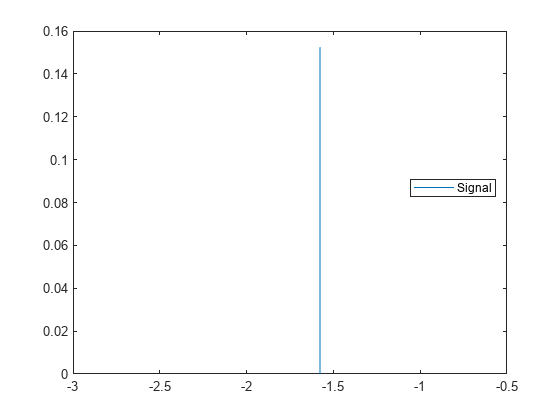

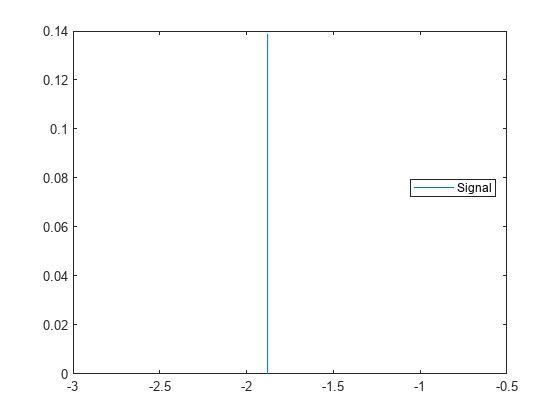

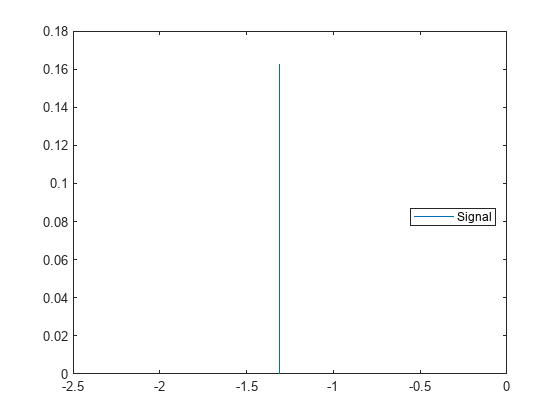

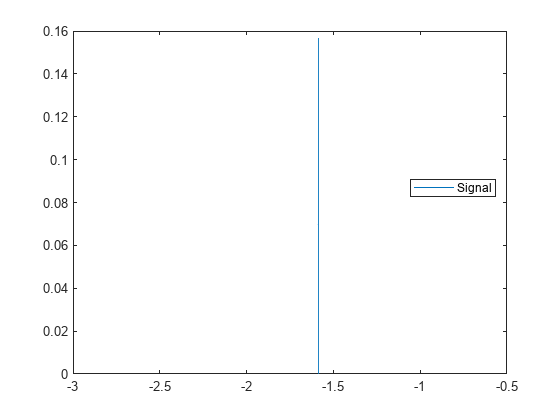

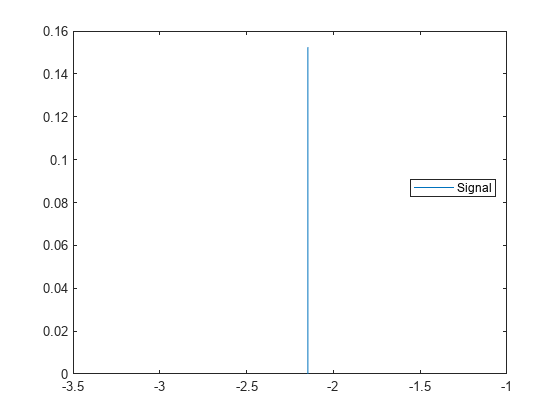

2119 of 2248 genes matched


[indexControlConsensus] = rFastcormics4cobra(model, fpkm(:,11:20), rownames, colnames(11:20),dico, consensusProportion, epsilon, optionalSettings, biomassReactionName, printFigures, path);

sampleModelsMatrixConsensus =zeros(numel(model.rxns), numel(colnames));
sampleModelsMatrixConsensus(indexControlConsensus,1)=1;
sampleModelsMatrixConsensus(indexCancerConsensus,2)=1;

## sample-specific models

2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched
LP10: Adaptive scaling factor did not work, switching to fixed scaling factor of 1e4


2119 of 2248 genes matched
LP10: Adaptive scaling factor did not work, switching to fixed scaling factor of 1e4


2119 of 2248 genes matched


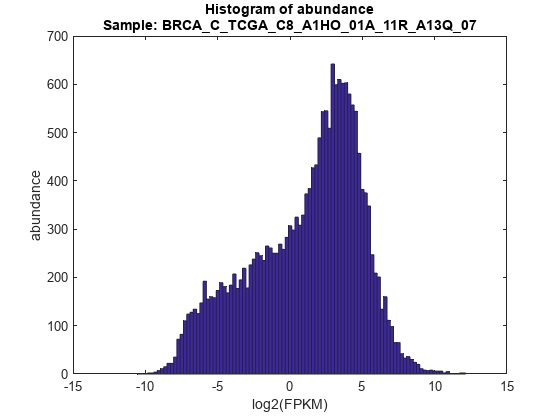

2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched
LP10: Adaptive scaling factor did not work, switching to fixed scaling factor of 1e4


2119 of 2248 genes matched


2119 of 2248 genes matched
LP10: Adaptive scaling factor did not work, switching to fixed scaling factor of 1e4


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


2119 of 2248 genes matched


sampleModelsMatrix =zeros(numel(model.rxns), numel(colnames));
for i = 1:numel(colnames) %for each sample
    [ sample_models] = rFastcormics4cobra(model, fpkm(:,i), rownames, colnames(i),dico, consensusProportion, epsilon, optionalSettings, biomassReactionName, printFigures);
     sampleModelsMatrix(sample_models,i)=1;
end

## 3.3. Basic model and pathway analysis

similarity between two models can be assessed via the Jaccard similarity index

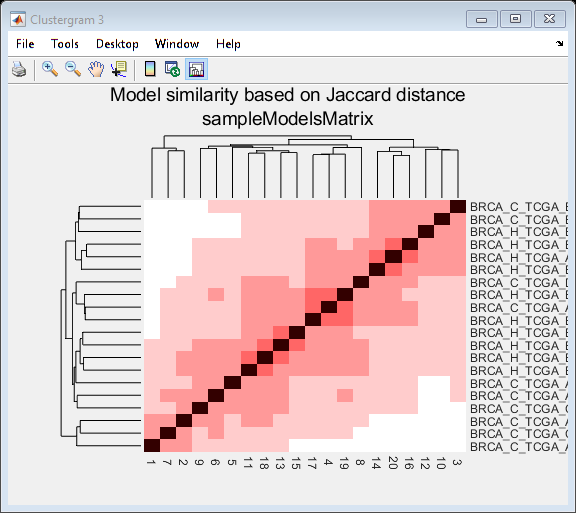

J = squareform(pdist(sampleModelsMatrix','jaccard'));
cgo_J = clustergram(1-J,...
    'RowLabels', colnames,...
    'ColumnLabels', [],...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor);
addTitle(cgo_J,{'Model similarity based on Jaccard distance','sampleModelsMatrix'})

## Pathway analysis

Pathways = table(unique(model.subSystems));
[pathways, ~, ub] = unique(model.subSystems);
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[~, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.consistent(ia) = T.path_counts(ib);

## Pathway information for the consensus models

[pathways, ~, ub] = unique(model.subSystems(find(sampleModelsMatrixConsensus(:,1))));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[~, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib) ;
Pathways.Properties.VariableNames{3} = 'cancer_consensus';
[pathways, ~, ub] = unique(model.subSystems(find(sampleModelsMatrixConsensus(:,2))));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[~, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib) ;
Pathways.Properties.VariableNames{4} = 'control_consensus';

## pathway information for the sample-specific models

for i=1:numel(colnames)
    [pathways, ~, ub] = unique(model.subSystems(find(sampleModelsMatrix(:,i))));
    path_counts = histc(ub, 1:length(pathways));
    T = table(pathways, path_counts);
    [~, ia, ib] = intersect(Pathways.Var1, T.pathways);
    Pathways.Var2(ia) = T.path_counts(ib) ;
    Pathways.Properties.VariableNames{4+i} = colnames{i};
end

## pathway activity rates

PathwayActivity = Pathways;
for i=3:size(PathwayActivity,2)
    PathwayActivity(:,i) = array2table(table2array(PathwayActivity(:,i))./table2array(PathwayActivity(:,2)));
end
% comparison of 2 conditions
% pathways with a difference higher than 20% 
diff_idx = find(abs(table2array(PathwayActivity(:,3))- table2array(PathwayActivity(:,4))) > 0.2);

## plotting

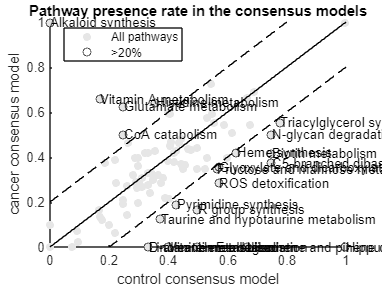

figure
hold on
scatter(table2array(PathwayActivity(:,3)),table2array(PathwayActivity(:,4)),'filled',...
    'MarkerFaceColor',[0.9 0.9 0.9])
scatter(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)),...
    'black')
ylabel('cancer consensus model')
xlabel('control consensus model')
title('Pathway presence rate in the consensus models')
line([0 1], [0,1],'Color','k')
line([0 0.8], [0.2,1],'Color','k','LineStyle','--')
line([0.2 1], [0,0.8],'Color','k','LineStyle','--')
legend({'All pathways','>20%'},"Location","best")
text(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)), PathwayActivity.Var1(diff_idx))

## comparison of multiple samples

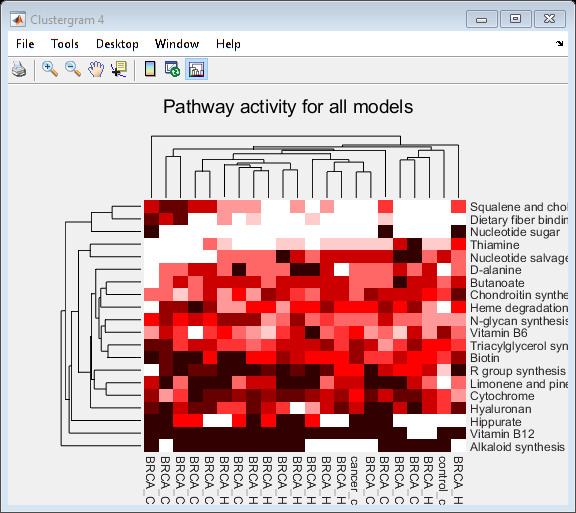

[~,I] = sort(sum(abs(table2array(PathwayActivity(:,3:end))-mean(table2array(PathwayActivity(:,3:end)),2)),2),'descend');
cgo = clustergram(table2array(PathwayActivity(I(1:20),3:end)),...
    'RowLabels', regexprep(PathwayActivity.Var1(I(1:20)),'metabolism',''),...
    'ColumnLabels', regexprep(PathwayActivity.Properties.VariableNames(3:end),'_TCGA.*',''),...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor);
addTitle(cgo,'Pathway activity for all models');

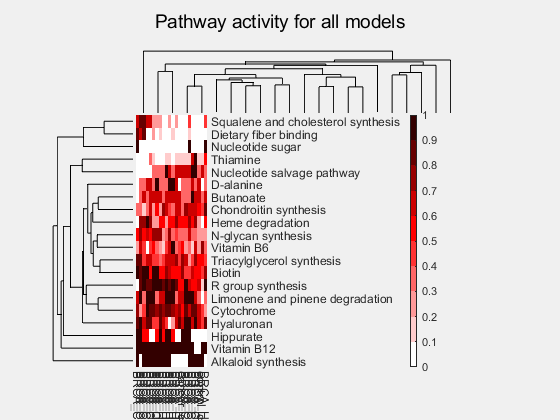

h = plot(cgo); set(h,'TickLabelInterpreter','none');
colorbar(h)